# Project 2: Motion Detection via Communication Signals

**张怡程 马文骁 高进 陈嘉祺**

## **Introduction**

#### **    Principles of Montion Detection**

    Moving objects reflects signal and causes time delay due to distance difference and frequency shift due to Doppler Effect of the radiation signal. The signal derectly comes from the illuminator is called reference signal, and the reflected one is called surveillance signal. We can analyze the two signals and find the time delay and frequency shift caused by the object and thus deriving the motion of it. Assume the transmitted signal to be $x\left(t\right)$, the reference signal to be $y_{\textrm{ref}} \left(t\right)$ and surveillance signal to be $y_{\textrm{sur}} \left(t\right)$. We can get


$$y_{\textrm{ref}} \left(t\right)=\alpha x\left(t-\tau_1 \right),{\;\;\;\;\;y}_{\textrm{sur}} \left(t\right)=\beta x\left(t-\tau_2 \right)e^{\textrm{j2}\pi f_d t}$$


    Where α and β stand for the  attenuation factor due to transmission, $\tau \;$stands for the time delay. Due to Doppler Effect


$$\tau_i =\frac{s_i }{c},\;\;\;\;\;f_d =\frac{vf_c }{c}$$


    Where $f_d$ is the Doppler frequency shift.

####     Cross-Correlation(ambiguity function)

Ambiguity function is aimed to estimate the relation of two signals. Here is it's defination:


$$\textrm{Cor}\left(\tau ,f\right)=\int_t^{t+T} y_{\textrm{sur}} \left(t\right)y_{\textrm{ref}}^{\ast } \left(t-\tau \right)e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}$$


where $y_{\textrm{sur}} \left(t\right)$ is the complex envelope of the signal received in the surveillance channel, $y_{\textrm{ref}} \left(t\right)$ is a (cleaned) replica of the transmitted signal, $\tau$ is the potential TDOA of the target echo signal, and $f$ is the potential corresponding bistatic Doppler. 

    And the maximum value of $\textrm{Cor}\left(\tau ,f\right)$, the corresponding variables of which are the kinematic information we get:


$$\left(\hat{\tau} ,\hat{f_d } \right)=\arg_{\tau ,f} \;\textrm{maxCor}\left(\tau ,f\right)$$


#### **    Time domain processing of signals**

    The signal is always transmitted at a higher frequency, which means we need to convert the target signal to the frequency centered on 0 Hz.Then filter out the high-frequency signal through the low-pass filter.

    The process of converting signal to the frequency centered on 0 Hz is called digital downconverter.  By the properies of fourier transform, we can achieve the expected result through the following formula.


$$y\left(t\right)=x\left(t\right)e^{-\textrm{j2}\pi f_{\textrm{ddc}} t}$$
 

    where $f_{\textrm{ddc}}$ is the central frequency of the target signal fragment.

    To filter out the high-frequency signal, we choose the 20 levels Butterworth low-pass filter:

## Result and Analysis

### Task 1 

% for data_index = 1:20
%     folderPath = sprintf('rawData\\data_%d\\', data_index);
%     addpath(folderPath);
% 
%     filename = sprintf('data_%d.mat', data_index); 
% 
%     load(filename);
%% The following code
% end

addpath('rawData\')

load('rawData\data_1\data_1.mat');

For convenience, we first only deal with 0.01s's data.

seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;fs=f_s;

The LPF filter we will use has this effect:

freqz(butter(20,0.5,'low'));

y1rd=sigAfterDDC(seq_ref1,fs);
x0r=sigAfterLPF(seq_ref1,fs);

plotSpectrum(seq_ref1,fs,1,3,'Raw'),title('Spectrum of Reference Signal','FontSize',15)
plotSpectrum(y1rd,fs,2,3,'After DDC')
plotSpectrum(x0r,fs,3,3,'After LPF')
plotTimeSig(seq_ref1,fs,1,3,'Raw'),title('Time Graph of Reference Signal','FontSize',15)
plotTimeSig(y1rd,fs,2,3,'After DDC')
plotTimeSig(x0r,fs,3,3,'After LPF')

y1sd=sigAfterDDC(seq_sur1,fs);
x0s=sigAfterLPF(seq_sur1,fs);

plotSpectrum(seq_sur1,fs,1,3,'Raw'),title('Spectrum of surveillance Signal','FontSize',15)
plotSpectrum(y1sd,fs,2,3,'After DDC')
plotSpectrum(x0s,fs,3,3,'After LPF')
plotTimeSig(seq_sur1,fs,1,3,'Raw'),title('Time Graph of surveillance Signal','FontSize',15)
plotTimeSig(y1sd,fs,2,3,'After DDC')
plotTimeSig(x0s,fs,3,3,'After LPF')

### Task 2

clear y1sd cur_time duration duration1 f_c f_s seq_ref1 seq_sur1 x0r x0s y1rd y1rf ans
xs1=sigAfterLPF(seq_sur,fs);%现在开始处理0.5s信号！
xr1=sigAfterLPF(seq_ref,fs);
[tau,fd]=corEst(xs1,xr1,'plot','Plot1')

load('rawData\data_2.mat');%这是data2
xs2=sigAfterLPF(seq_sur,fs);
xr2=sigAfterLPF(seq_ref,fs);
[tau2,fd2]=corEst(xs2,xr2,'plot','Plot2')

corTime(tau,xs1,xr1)

### Task 3

function corTime(ysur,yref,varargin)

end

### Basical function

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function plotTimeSig(x,fs,a,n,Title)
    if a==1
        figure
    end
    t=xTime(x,fs);
    subplot(n,1,a),plot(t.*1e3,real(x)),subtitle(Title)
    ylabel("Amplitude"),ylim([-2e-3,2e-3])%注意这里的ylim和PPT不一样
    if a==n
        xlabel("Time(ms)")
    end
end

function plotSpectrum(x,fs,a,n,Title)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    if a==1
        figure
    end
    subplot(n,1,a),plot(f./10^6,20*log10(abs(H))),subtitle(Title)
    ylabel('Amplitude(dB)'),ylim([-80,0])
    if a==n
        xlabel('Frequency(MHz)')
    end
end

### Task 1 function: DDC and filter

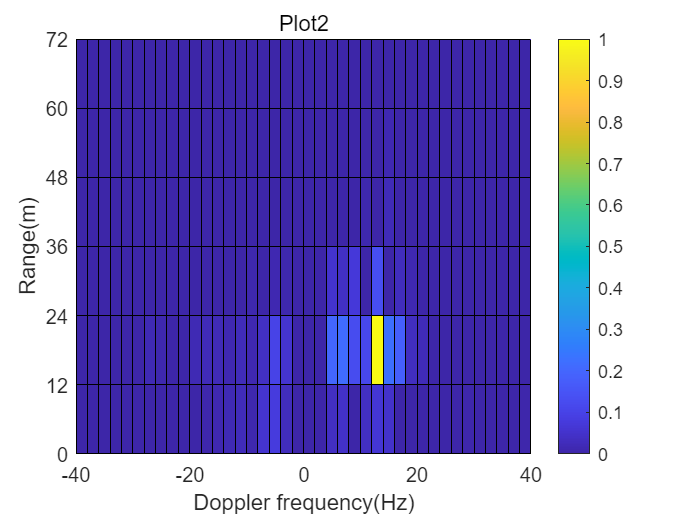

tau2 = 4.0000e-08

fd2 = 12

function x_moved=sigAfterDDC(x,fs)
    f_ddc=-3e6;

    t=xTime(x,fs);
    x_moved=x.*exp(-1j*2*pi*f_ddc.*t);
end

function x_filtered=sigAfterLPF(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc.*t);
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end

### Task 2 function: Ambiguity function

function [tau,fd]=corEst(y_surv,y_ref,varargin)
    
    %可选参数: 是否作图?'plot','save'
    fs=25000000;
    corMat=zeros(7,41);
    Tau=linspace(0,1/fs*6,7);
    Fd=linspace(-40,40,41);
    for i=1:7
        for j=1:41
            corMat(i,j)=corRange(Tau(i),Fd(j),y_surv,y_ref);
        end
    end
    [~,I]=max(corMat(:));%寻找corMat中最大值索引
    [m,n]=ind2sub(size(corMat),I);%索引转为横纵索引

    tau=Tau(m);
    fd=Fd(n);
    numVar=nargin-2;
    %是否作图
    if isempty(varargin)
        return
    elseif strcmp(varargin{1},'plot')||strcmp(varargin{1},'save')
        if numVar<2
            disp('No enough arguments. Check title and/or filename.')
            return
        end
        h=figure;

        minVal = min(corMat(:));
        maxVal = max(corMat(:));

        % 进行 0-1 标准化,3次方加强效果
        corMat=((corMat - minVal) / (maxVal - minVal)).^3;
        
        pcolor(Fd,Tau.*3e8,corMat);colorbar
        
        xlabel("Doppler frequency(Hz)"),ylabel("Range(m)"),yticks(0:12:72)
        title(varargin{2})

        if strcmp(varargin{1},'save')
            if numVar<3
                disp('Filename not detected!')
                return
            end
            saveas(h,varargin{3},'png')
        end
    else 
        disp('Wrong input.')
    end
end

function Cor=corRange(tau,fd,y_surv,y_ref,varargin)
    numVar=nargin-4;
    %可选参数: 采样率、方法

    fs=25000000;
    Type='dot';%这是默认采样率和算法，fft做好后默认要改成fft

    for i=1:numVar%根据可变参数情况设置采样率和算法
        if isnumeric(varargin{i})
            fs=varargin{i};
        elseif ischar(varargin{i})
            Type=varargin{i};
        end
    end

    zero_compensation=zeros(1,fix(tau*fs));%时延后补长信号以对齐
    y_surv=[y_surv,zero_compensation];
    y_ref=[zero_compensation,y_ref];
    
    %以下是侦测方法名选择方法
    if strcmp(Type,'fft')
        %TODO：fft方法
    elseif strcmp(Type,'dot')
        Cor=abs(sum(y_surv.*conj(y_ref).*exp_component(length(y_surv),fd,fs)));
    elseif strcmp(Type,'for')
        Cor=0;
        for k=1:length(y_surv)
            Cor=Cor+y_surv(k)*conj(y_ref(k))*exp(-2j*pi*fd*k/fs);
        end
        Cor=abs(Cor);
    else
        disp('Invalid method name.')
        return;
    end
end

function y=exp_component(n,fd,fs)%dot法要调用的函数
    y=exp((-2i*pi*fd/fs).*linspace(0,n-1,n));
end